# Radar Modeling and Simulation

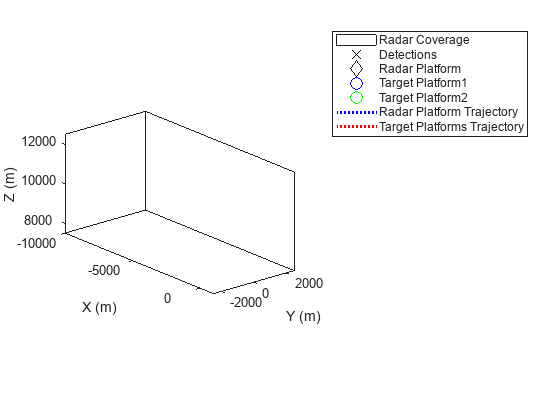

clc
close all
clear variables
tp = helperCreateDetectionPlotters();

## Set up Simulation

% create scenario
scenario = radarScenario;
scenario.StopTime = 20; % s
scenario.UpdateRate = 0;

## Model Multi Target Scenario

Load and Update Radar Properties

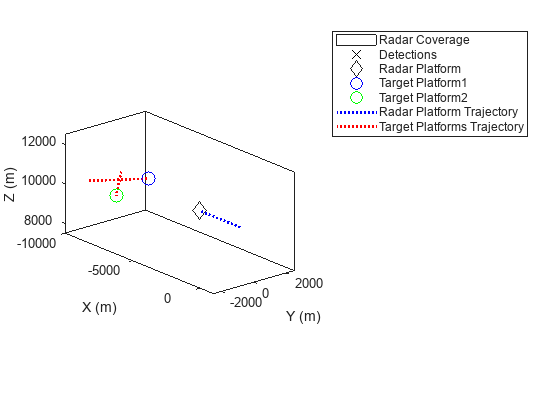

% Load radar object from previous chapter
load("radar.mat","radar")

% Release object properties
release(radar)

% Update radar properties
radar.ScanMode = "Electronic";
radar.ElectronicElevationLimits = [-10 10];
radar.ElectronicAzimuthLimits = [-20 20];
radar.UpdateRate = 100;
radar.FalseAlarmRate = 1e-7;
radar.RangeRateLimits = [-500 500];

% Create radar platform
radarPlatform = platform(scenario);

% Add radar to platform
radarPlatform.Sensors = radar;

% Create target platforms
targetPlatform1 = platform(scenario);
targetPlatform2 = platform(scenario);

% Update radar platform trajectory
radarPlatform.Trajectory = kinematicTrajectory("Velocity",[-150 0 0],"Position",[0 0 10e3]);

% Update target platforms trajectories
targetPlatform1.Trajectory = kinematicTrajectory("Velocity",[100 100 10],"Position",[-10e3 -1000 9.8e3]);
targetPlatform2.Trajectory = kinematicTrajectory("Velocity",[100 -100 -10],"Position",[-10e3 1000 9.8e3]);

% Visualize scenario
[radarWayPoints, targetWayPoints] = getWayPoints(scenario);
helperVisualizeTrajectory(tp,radarWayPoints,targetWayPoints)
while advance(scenario)
    helperVisualizePlatforms(tp,radarPlatform,[targetPlatform1 targetPlatform2])
end

restart(scenario)

## Model Target Detection

% Display simulation times
while advance(scenario)
    disp(scenario.SimulationTime)
end

    0.0100

    0.0200

    0.0300

    0.0400

    0.0500

    0.0600

    0.0700

    0.0800

    0.0900

    0.1000

    0.1100

    0.1200

    0.1300

    0.1400

    0.1500

    0.1600

    0.1700

    0.1800

    0.1900

    0.2000

    0.2100

    0.2200

    0.2300

    0.2400

    0.2500

    0.2600

    0.2700

    0.2800

    0.2900

    0.3000

    0.3100

    0.3200

    0.3300

    0.3400

    0.3500

    0.3600

    0.3700

    0.3800

    0.3900

    0.4000

    0.4100

    0.4200

    0.4300

    0.4400

    0.4500

    0.4600

    0.4700

    0.4800

    0.4900

    0.5000

    0.5100

    0.5200

    0.5300

    0.5400

    0.5500

    0.5600

    0.5700

    0.5800

    0.5900

    0.6000

    0.6100

    0.6200

    0.6300

    0.6400

    0.6500

    0.6600

    0.6700

    0.6800

    0.6900

    0.7000

    0.7100

    0.7200

    0.7300

    0.7400

    0.7500

    0.7600

    0.7700

    0.7800

    0.7900

    0.8000

    0.8100

    0.8200

    0.8300

    

% Display current simulation status
disp(scenario.SimulationStatus)

    Completed



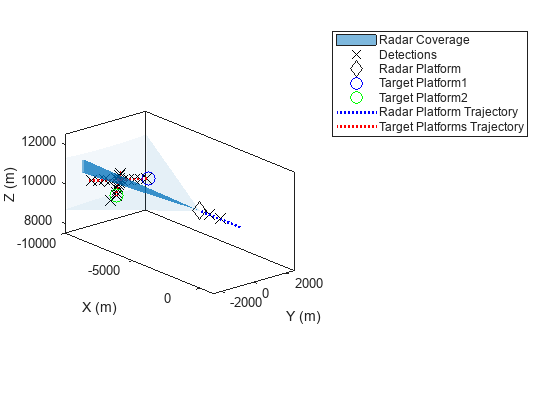

% Revert scenario to beginning
restart(scenario)

% Collect detections
detTimes = [];
detections = {};
while advance(scenario)
    % collect detections
    currDets = detect(scenario);
    if ~isempty(currDets)
        % append new detections to collection
        detections{end+1} = currDets; %#ok<SAGROW>
        detTimes = [detTimes; cellfun(@(x) x.Time,currDets,"UniformOutput",true)]; %#ok<AGROW> 
    end
end
% Visualize detections
helperVisualizeDetections(tp,scenario,radarPlatform,targetPlatform1,targetPlatform2)

## Model Target Tracking

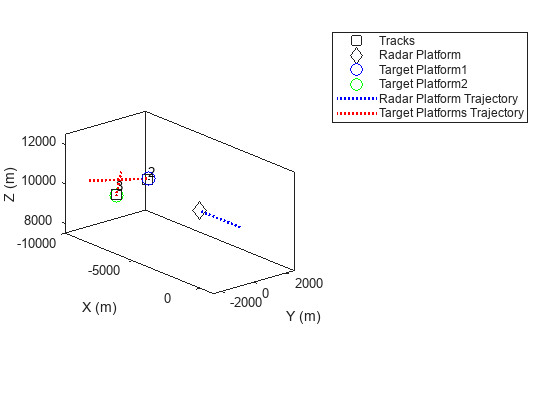

% Update target report format
release(radar)
radar.TargetReportFormat = "Tracks";
radar.TrackCoordinates = "Scenario";
radar.FilterInitializationFcn = @initcvekf;

restart(scenario)
trackReport = [];
while advance(scenario)
    targets = targetPoses(radarPlatform);
    platformPose = pose(radarPlatform);
    tracks = radar(targets,platformPose,scenario.SimulationTime);
    if (~isempty(tracks))
        trackReport = [trackReport; tracks]; %#ok<AGROW>
    end
end
% Visualize tracks on theater plot
helperVisualizeTracks(scenario,radarPlatform,targetPlatform1,targetPlatform2,radarWayPoints,targetWayPoints)

## Radar Transceiver

%radarIQ = radarTransceiver(radar)

release(radar)
radar.UpdateRate = 10;
scenario.UpdateRate = 10;
radar.MaxUnambiguousRadialSpeed = 60;

radarIQ = radarTransceiver(radar);
radarPlatform.Sensors = radarIQ;

## Model Target Detections for Signal Level Modeling

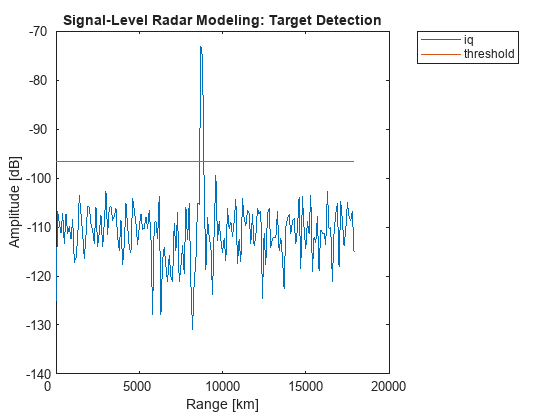

% Calculate noise power
noisePower = noisepow(bandwidth(radarIQ.Waveform),radarIQ.Receiver.NoiseFigure,radarIQ.Receiver.ReferenceTemperature);
% Calculate required SNR threshold for required false alarm ratio
thresholdSNR = npwgnthresh(radar.FalseAlarmRate);
% Calculate signal threshold for the given noise power
threshold = sqrt(radarIQ.TransmitAntenna.Sensor.getNumElements()*noisePower*db2pow(thresholdSNR));
% Signal processing objects
steer = phased.SteeringVector("SensorArray",radarIQ.ReceiveAntenna.Sensor);
rangeResp = phased.RangeResponse("SampleRate",radarIQ.Receiver.SampleRate);
% Scenario loop
radarData = [];
restart(scenario)
while advance(scenario) && scenario.SimulationTime < 5.3
    t = scenario.SimulationTime;
    targets = targetPoses(radarPlatform);
    [iqSignal,config] = radarIQ(targets,t);
    if (nnz(abs(t - detTimes) < 1e-4))
        radarData = helperGetDetectionCoordinates(radarPlatform,radarIQ,steer,rangeResp,iqSignal,threshold,config,t,radarData);
    end
end

function tp = helperCreateDetectionPlotters()
% all the plotters are hosted within theaterPlot. Hence, there is no need
% to return those values.
% Create theater plot to host plotters
tp = theaterPlot("XLimits",[-10e3 1e3],"YLimits",[-2500 2500],"ZLimits",[7.5e3 12.5e3]);
view(50,20)
% Create coverage plotter to visualize radar coverage
covPlotter = coveragePlotter(tp,"DisplayName","Radar Coverage","Tag","covPlotter"); %#ok<NASGU> 
% Create detection plotter to visualize detections
detPlotter = detectionPlotter(tp,"DisplayName","Detections","Tag","detPlotter","Marker","x","MarkerSize",10,"MarkerEdgeColor","k"); %#ok<NASGU> 
% Create platform plotters
radarPlotter = platformPlotter(tp,"DisplayName","Radar Platform","Tag","radarPlotter","Marker","d","MarkerSize",10); %#ok<NASGU> 
targetPlotter1 = platformPlotter(tp,"DisplayName","Target Platform1","Tag","targetPlotter1","Marker","o","MarkerSize",10,"MarkerEdgeColor","b"); %#ok<NASGU> 
targetPlotter2 = platformPlotter(tp,"DisplayName","Target Platform2","Tag","targetPlotter2","Marker","o","MarkerSize",10,"MarkerEdgeColor","g"); %#ok<NASGU> 
% create trajectory plotters
radarTrjPlotter = trajectoryPlotter(tp,"DisplayName","Radar Platform Trajectory","Tag","radarTrjPlotter","LineStyle",":","LineWidth",2,"Color","b"); %#ok<NASGU> 
targetTrjPlotter = trajectoryPlotter(tp,"DisplayName","Target Platforms Trajectory","Tag","targetTrjPlotter","LineStyle",":","LineWidth",2,"Color","r"); %#ok<NASGU> 
end

function tp = helperCreateTrackingPlotters()
% all the plotters are hosted within theaterPlot. Hence, there is no need
% to return those values.
% Create theater plot to host plotters
tp = theaterPlot("XLimits",[-10e3 1e3],"YLimits",[-2500 2500],"ZLimits",[7.5e3 12.5e3]);
view(50, 20)
% Create detection plotter to visualize detections
trPlotter = trackPlotter(tp,"DisplayName","Tracks","Tag","trPlotter"); %#ok<NASGU> 
% Create platform plotters
radarPlotter = platformPlotter(tp,"DisplayName","Radar Platform","Tag","radarPlotter","Marker","d","MarkerSize",10); %#ok<NASGU> 
targetPlotter1 = platformPlotter(tp,"DisplayName","Target Platform1","Tag","targetPlotter1","Marker","o","MarkerSize",10,"MarkerEdgeColor","b"); %#ok<NASGU> 
targetPlotter2 = platformPlotter(tp,"DisplayName","Target Platform2","Tag","targetPlotter2","Marker","o","MarkerSize",10,"MarkerEdgeColor","g"); %#ok<NASGU> 
% create trajectory plotters
radarTrjPlotter = trajectoryPlotter(tp,"DisplayName","Radar Platform Trajectory","Tag","radarTrjPlotter","LineStyle",":","LineWidth",2,"Color","b"); %#ok<NASGU> 
targetTrjPlotter = trajectoryPlotter(tp,"DisplayName","Target Platforms Trajectory","Tag","targetTrjPlotter","LineStyle",":","LineWidth",2,"Color","r"); %#ok<NASGU> 
end

function helperVisualizeTrajectory(tp,radarWaypoints,targetWaypoints)

radarTrjPlotter = tp.Plotters(find({tp.Plotters.Tag} == "radarTrjPlotter"));
targetTrjPlotter = tp.Plotters(find({tp.Plotters.Tag} == "targetTrjPlotter"));

% visualize trajectory
plotTrajectory(radarTrjPlotter,radarWaypoints)
plotTrajectory(targetTrjPlotter,targetWaypoints)

end

function helperVisualizePlatforms(tp,radarPlatform,targetPlatforms)

radarPlotter = tp.Plotters(find({tp.Plotters.Tag} == "radarPlotter"));
targetPlotter1 = tp.Plotters(find({tp.Plotters.Tag} == "targetPlotter1"));
targetPlotter2 = tp.Plotters(find({tp.Plotters.Tag} == "targetPlotter2"));

pRadar = pose(radarPlatform);
pTarget1 = pose(targetPlatforms(1));
pTarget2 = pose(targetPlatforms(2));
plotPlatform(radarPlotter, pRadar.Position)
plotPlatform(targetPlotter1, pTarget1.Position)
plotPlatform(targetPlotter2, pTarget2.Position)
end

function helperVisualizeDetections(tp,scenario,radarPlatform,targetPlatform1,targetPlatform2)
restart(scenario)
% Get covPlotter from tp object
covPlotter = tp.Plotters(find({tp.Plotters.Tag} == "covPlotter"));
detPlotter = tp.Plotters(find({tp.Plotters.Tag} == "detPlotter"));

detections = cell(1, 0);
measurements = [];
while advance(scenario)
    helperVisualizePlatforms(tp,radarPlatform,[targetPlatform1 targetPlatform2]);
    % collect detections
    currDets = detect(scenario);
    if ~isempty(currDets)
        % append new detections to collection
        detections{end+1} = currDets;  %#ok<AGROW> 
        for ii = 1:length(currDets)
            measurements(end+1,:) = currDets{ii}.Measurement(1:3).';  %#ok<AGROW> 
        end
        plotDetection(detPlotter,measurements)
    end
    % plot coverage
    plotCoverage(covPlotter,coverageConfig(scenario))
end
end

function helperVisualizeTracks(scenario,radarPlatform,targetPlatform1,targetPlatform2,radarWaypoints,targetWaypoints)
tp = helperCreateTrackingPlotters();
restart(scenario)
% Get covPlotter from tp object
trPlotter = tp.Plotters(find({tp.Plotters.Tag} == "trPlotter"));
radarTrjPlotter = tp.Plotters(find({tp.Plotters.Tag} == "radarTrjPlotter"));
targetTrjPlotter = tp.Plotters(find({tp.Plotters.Tag} == "targetTrjPlotter"));

% visualize trajectory
plotTrajectory(radarTrjPlotter,radarWaypoints)
plotTrajectory(targetTrjPlotter,targetWaypoints)

restart(scenario)
while advance(scenario)
    helperVisualizePlatforms(tp,radarPlatform,[targetPlatform1 targetPlatform2])
    trackPositions = [];
    trackVelocities = [];
    trackLabels = {};
    targets = targetPoses(radarPlatform);
    sensorPose = pose(radarPlatform);
    tracks = radarPlatform.Sensors{1}(targets, sensorPose, scenario.SimulationTime);
    if (~isempty(tracks)) 
        for ii = 1:length(tracks)
            trackPositions(end+1,:) = tracks(ii).State(1:2:end).';  %#ok<AGROW> 
            trackVelocities(end+1,:) = tracks(ii).State(2:2:end).';  %#ok<AGROW> 
            trackLabels{end+1} = char(num2str(tracks(ii).ObjectAttributes.TargetIndex));  %#ok<AGROW> 
        end
        plotTrack(trPlotter,trackPositions,trackVelocities,trackLabels)
    end
end
end

function radarData = helperGetDetectionCoordinates(radarPlatform,radarIQ,steer,rangeResp,iqSignal,threshold,config,t,radarData)
steeringVector = steer(radarIQ.TransmitAntenna.OperatingFrequency,config.ElectronicAngle);
estimator = phased.BeamscanEstimator2D("SensorArray",radarIQ.TransmitAntenna.Sensor,"OperatingFrequency",radarIQ.TransmitAntenna.OperatingFrequency, ...
    "DOAOutputPort",true,"AzimuthScanAngles",(-15:0.1:15),"ElevationScanAngles",(-10:0.1:10));
iqSignal = iqSignal(:,:,1);
[iqSignalRangeProcessed,rangeBins] = rangeResp(iqSignal,radarIQ.Waveform.getMatchedFilter());
iq = iqSignalRangeProcessed*steeringVector;

[~,max_idx] = max(abs(iq));
[~,doas] = estimator(iqSignalRangeProcessed(max_idx,:));

if abs(iq(max_idx))>threshold
    rangeEst = rangeBins(max_idx);
    measSensor = [doas(1); doas(2); rangeEst];
    measFromPlatform = local2globalcoord(measSensor,"sr",config.OriginPosition,config.Orientation);
    measFromScenario = local2globalcoord(measFromPlatform,"rr",radarPlatform.Position.', ...
        rotz(radarPlatform.Orientation(1))*roty(radarPlatform.Orientation(2))*rotx(radarPlatform.Orientation(3)));
    detStruct = struct("Time",t,"Measurement",measFromScenario);
    radarData = [radarData; detStruct];
    % HAVE CLASS ADD THESE LINES OF CODE
    plot(rangeBins,mag2db(abs(iq)))
    hold on
    plot(rangeBins,ones(size(rangeBins))*mag2db(threshold))
    hold off
    legend("iq","threshold")
    title("Signal-Level Radar Modeling: Target Detection")
    xlabel("Range [km]")
    ylabel("Amplitude [dB]")
end
end

function [radarWayPoints,targetWayPoints] = getWayPoints(sc)
waypoints = [];
while advance(sc)
    waypoints = [waypoints; sc.platformPoses.Position]; %#ok<AGROW> 
end
radarWayPoints = {waypoints(:,1:3)};
targetWayPoints = {waypoints(:,4:6), waypoints(:,7:9)};
restart(sc)
end